Inputting data from a xls file that I created in Python as I wanted to have data on dow, month, and is_holiday. Snippet of my python code

`data` `=` `pd``.``read_excel``(``'GEFcom2014 Data\GEFCom2014-E.xlsx'``,` `skiprows=``range``(``1``,``17545``))`

`data``[``'month'``]` `=`` data.Date``.``dt``.``month`

`data``[``'dow'``]` `=`` data.Date``.``dt``.``dayofweek` 

`data``[``'hour'``]` `=`` data``.``Date``.``dt``.``hour`

`us_holiday` `=` `holidays``.``US``()``data``[``'is_holiday'``]` `=` `1` `*` `data``.``Date``.``dt``.``date``.``apply``(``lambda` `x``:` `x` `in` `us_holiday``)`

`data``.``drop``([``'Date'``,` `'Hour'``],``1``,` `inplace``=``True``)`

`c` `=` `list``(``data``.``columns``)``c` `=` `c``[``1``:]` `+` `c``[:``1``]`

`data` `=` `data``[``c``]`

data = xlsread('Project_Data.xlsx');
save Project2_data.mat data

Plotting a temperature vs flow graph

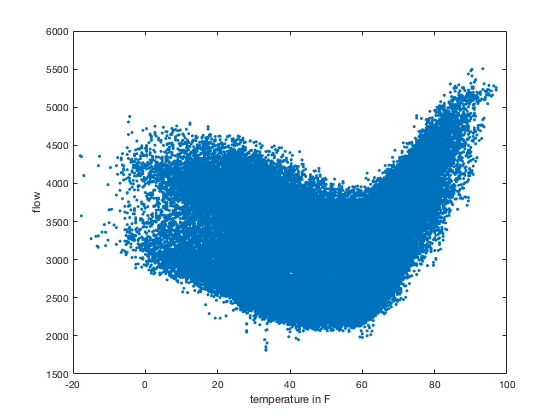

figure;
plot(data(:,6),data(:,7) ,'.')
xlabel('temperature in F')
ylabel('flow')

In this section I divide the data set into training and testing. Additionally, I set the values for CDD and HDD.


$$CDD = max(T_i-65,0)$$



$$HDD = max(65-T_i,0)$$


dataTrainEnd = floor(.8*size(data)); 
dataTrain = data(1:dataTrainEnd,:);
dataTest = data(dataTrainEnd:end, :);
CDD = zeros(78888,1);
HDD = zeros(78888,1);
for i = 1:size(CDD)
    CDD(i) = max(data(i,6)-65, 0);
    HDD(i) = max(65- data(i,6), 0);
end

In this section I set the values for all the variables I will require. Additionally, I perform linear transformations on the day of the week, and hour of the week. 

CDDTrain = CDD(1:dataTrainEnd,1);
HDDTrain = HDD(1:dataTrainEnd,1);
MonthSin = sin((2*pi*(dataTrain(:,2)))./12);
MonthCos = cos((2*pi*(dataTrain(:,2)))./12);
is_holidayTrain = dataTrain(:,5);
dowTrain = dataTrain(:,3);
dowSinTrain = sin((2*pi*(dowTrain+1))./7);
dowCosTrain = cos((2*pi*(dowTrain+1))./7);
hourTrain = dataTrain(:,4);
hourTrainSin = sin((2*pi.*hourTrain)./24);
hourTrainCos = cos((2*pi.*hourTrain)./24);
flowTrain = dataTrain(:,7);


%Test variables
CDDTest = CDD(dataTrainEnd:end,1);
HDDTest = HDD(dataTrainEnd:end,1);
is_holidayTest = dataTest(:,5);
dowTest = dataTest(:,3);
dowSinTest = sin((2*pi*(dowTest+1))./7);
dowCosTest = cos((2*pi*(dowTest+1))./7);
hourTest = dataTest(:,4);
hourTestSin = sin((2*pi.*hourTest)./24);
hourTestCos = cos((2*pi.*hourTest)./24);
flowTest = dataTest(:,7);
MonthSinTest = sin((2*pi*(dataTest(:,2)))./12);
MonthCosTest = cos((2*pi*(dataTest(:,2)))./12);

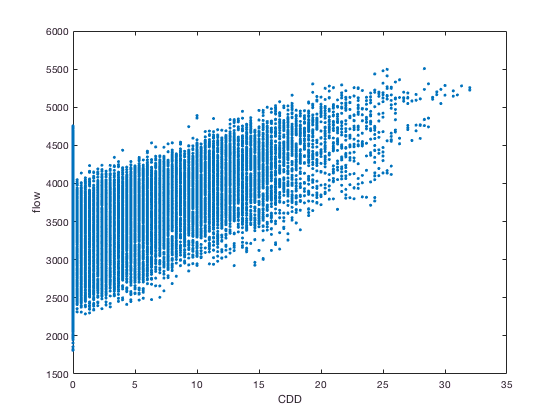

figure;
plot(CDDTrain,flowTrain, '.')
xlabel('CDD')
ylabel('flow')

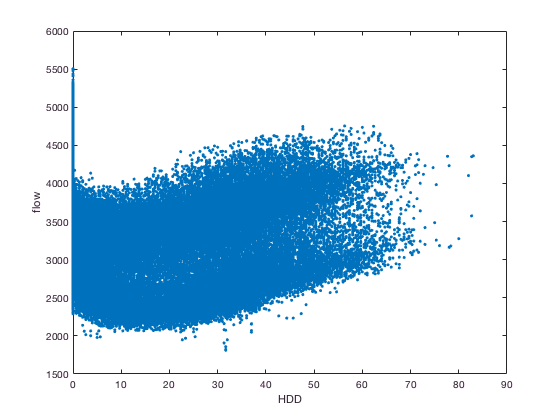

plot(HDDTrain,flowTrain, '.')
xlabel('HDD')
ylabel('flow')

A model for this data looks like :


$$y = a_0 +a_1x_1+a_2x_2+..+a_nx_n$$


Multiple regressions solves for coefficents $a_0, a_1, and a_2$. 

Following line forms a matrix , X which has the first row set as 1, as it is necessary to do so in statistics to have a constant term or a basic flow. It contains the variable is_holiday.

X = [ones(size(CDDTrain)) CDDTrain HDDTrain is_holidayTrain hourTrainSin hourTrainCos dowSinTrain dowCosTrain MonthSin MonthCos];
Y = flowTrain;

Solve for the different coefficents. 

a = X\Y

a =    1.0e+03 *

    2.9397
    0.0506
    0.0151
   -0.1420
   -0.4562
   -0.3699
    0.0679
   -0.1408
   -0.1415
   -0.0770


The equation for this model is 


$$y = 2939+50x_1+15x_2-142x_3-456x_4-369x_5+68x_6- 140x_7-141x_8-77x_9$$


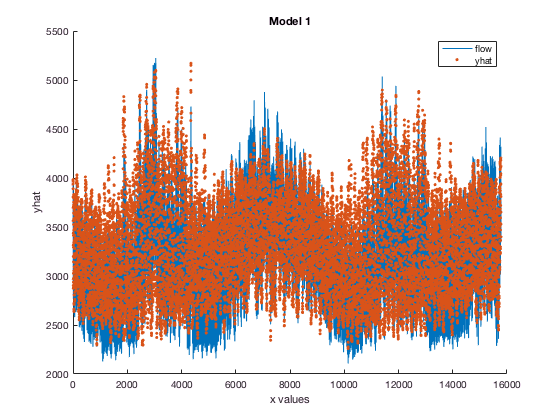

 figure;  
 hold on;
 plot(flowTest);
 yhat = a(1) + (a(2).*CDDTest) + (a(3).*HDDTest) +(a(4).*is_holidayTest)+ (a(5).*hourTestSin)+ (a(6).*hourTestCos )+ (a(7).*dowSinTest) + (a(8).*dowCosTest) + (a(9).*MonthSinTest)+(a(10).*MonthCosTest);
 plot(yhat,'.');
 xlabel('x values')
 ylabel('yhat')
 title('Model 1')
 legend('flow', 'yhat')
 hold off;

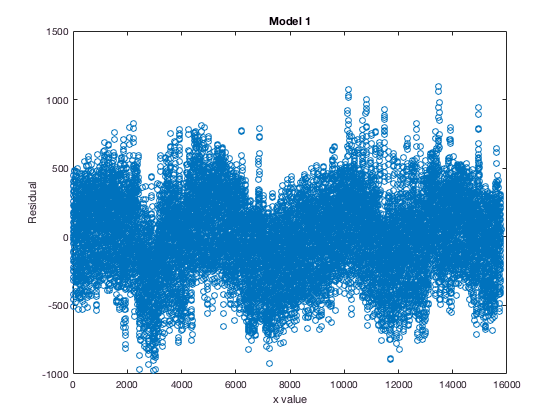

res_vals = (yhat -flowTest)';
figure; 
plot(res_vals,'o');
xlabel('x value')
ylabel('Residual')
title('Model 1')

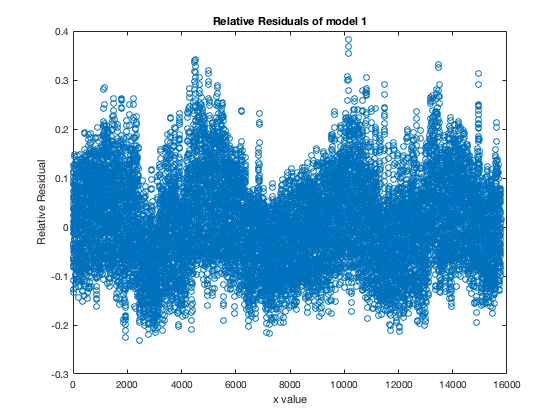

figure; 
plot(res_vals'./flowTest, 'o');
xlabel('x value')
ylabel('Relative Residual')
title('Relative Residuals of model 1')

Createst a matrix x without isholiday variable

x = [ones(size(CDDTrain)) CDDTrain HDDTrain hourTrainSin hourTrainCos dowSinTrain dowCosTrain MonthSin MonthCos];
y = flowTrain;

calculates the coefficent values

b = x\y

b =    1.0e+03 *

    2.9352
    0.0504
    0.0151
   -0.4567
   -0.3702
    0.0649
   -0.1432
   -0.1412
   -0.0814


The equation for this model is 


$$y = 2935+50x_1+15x_2-456x_3-370x_4+65x_5-143x_6-141x_7-81x_8$$


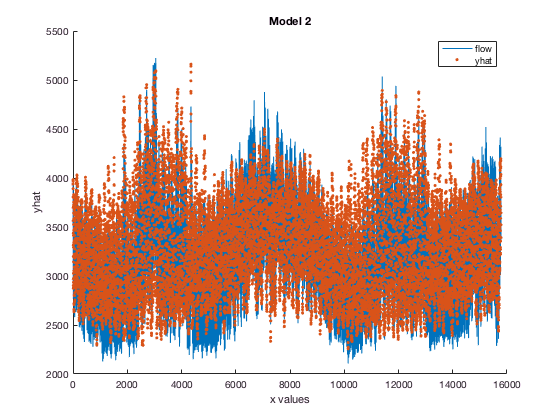

figure;  
hold on;
plot(flowTest);
yhat2 = b(1)+ (b(2).*CDDTest) + (b(3).*HDDTest)+(b(4).*hourTestSin)+(b(5).*hourTestCos)+(b(6).*dowSinTest)+(b(7).*dowCosTest)+b(8)*MonthSinTest + b(9)*MonthCosTest;
plot(yhat2,'.');
xlabel('x values')
ylabel('yhat')
title('Model 2')
legend('flow', 'yhat')
hold off;

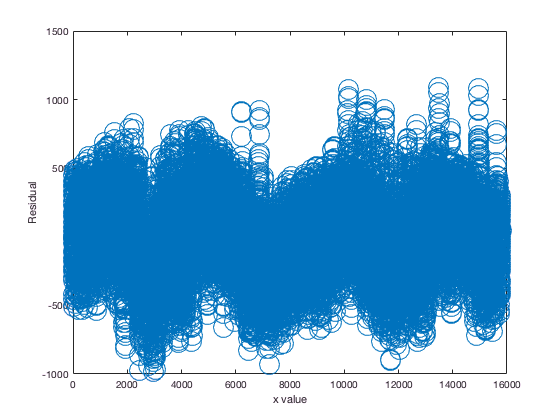

res_vals2 = (yhat2 -flowTest)';
figure; 
plot(res_vals2,'o', 'MarkerSize', 20);
xlabel('x value')
ylabel('Residual')

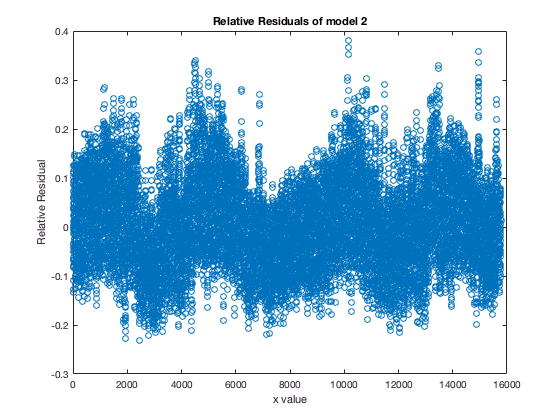


figure; 
plot(res_vals2'./flowTest,'o');
xlabel('x value')
ylabel('Relative Residual')
title('Relative Residuals of model 2')

In the following section I find the residuals on the days it was a holiday for the models trained with taking in account the variables and that trained without it. 

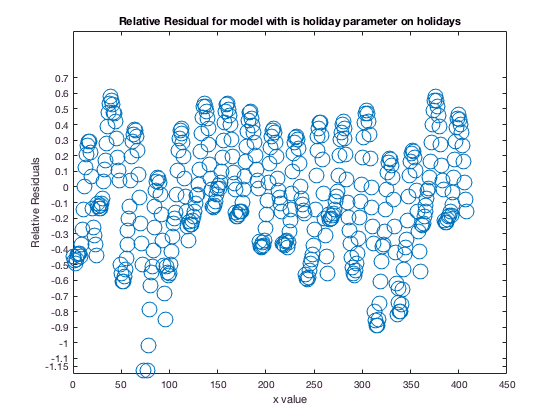

residual_withHoliday = (yhat(is_holidayTest==1)-Y(is_holidayTest==1));
figure; 
plot(residual_withHoliday ./flowTest(is_holidayTest==1),'o', 'MarkerSize', 15);
xlabel('x value')
ylabel('Relative Residuals')
set(gca, 'YLim', [-1.2, max([1, max(ylim)])]);
yticks([-1.15 -1.1 -1.0 -.9 -.8 -.7 -.6 -.5 -.4 -.3 -.2 -.1 0 .1 .2 .3 .4 .5 .6 .7])

title('Relative Residual for model with is holiday parameter on holidays')

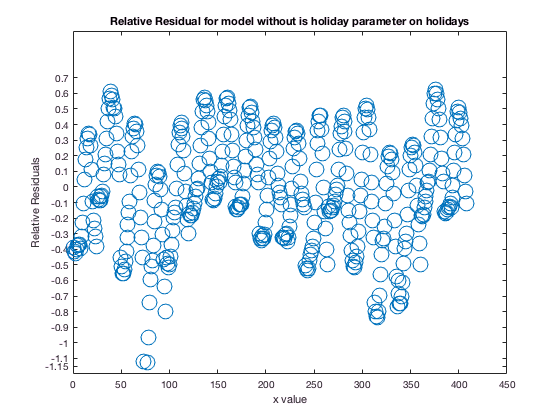

residual_withoutHoliday =((yhat2(is_holidayTest==1)-y(is_holidayTest==1)));
figure; 
plot(residual_withoutHoliday./flowTest(is_holidayTest==1),'o', 'MarkerSize', 15);
set(gca, 'YLim', [-1.2, max([1, max(ylim)])]);
yticks([-1.15 -1.1 -1.0 -.9 -.8 -.7 -.6 -.5 -.4 -.3 -.2 -.1 0 .1 .2 .3 .4 .5 .6 .7])
xlabel('x value')
ylabel('Relative Residuals')
title('Relative Residual for model without is holiday parameter on holidays')